# 4.5. Фильтры и предельные частоты

#### Усиление в дБ

clear
syms A P1 P2 V1 V2
A==10*log(P2/P1)==20*log(abs(V2/V1))   % дБ

$$ans = \left(A=10\,\log\left(\frac{P_{2}}{P_{1}}\right)\right)=20\,\log\left(\frac{\left|V_{2}\right|}{\left|V_{1}\right|}\right)$$

#### Фильтр верхних частот

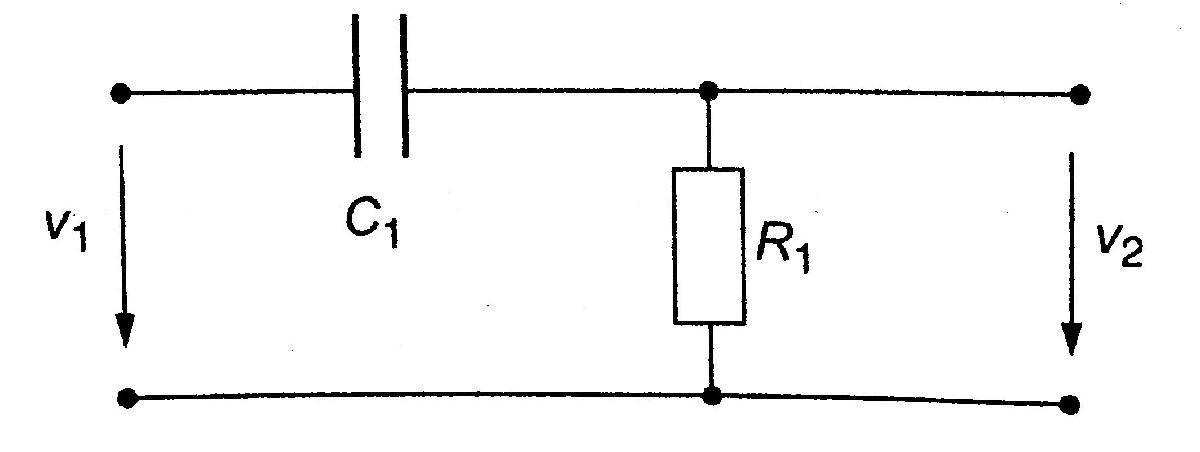

syms A v1 v2 f_L f
A==v2/v1==1/(1-j*f_L/f)

$$ans = \left(A=\frac{v_{2}}{v_{1}}\right)=-\frac{1}{-1+\frac{f_{L}\,\mathrm{i}}{f}}$$

abs(A)==(1+(f_L/f)^2)^(-1/2)

$$ans = \left|A\right|=\frac{1}{\sqrt{\frac{{f_{L}}^{2}}{f^{2}}+1}}$$

Частота границы пропускания (3 дБ)

syms f_L R1 C1
f_L==1/(2*pi*R1*C1)

$$ans = f_{L}=\frac{1}{2\,C_{1}\,R_{1}\,\pi }$$

Сдвиг фазы v2

syms theta 
theta==atan(f_L/f)

$$ans = \theta =\mathrm{atan}\left(\frac{f_{L}}{f}\right)$$

#### Фильтр низкочастотного пропускания

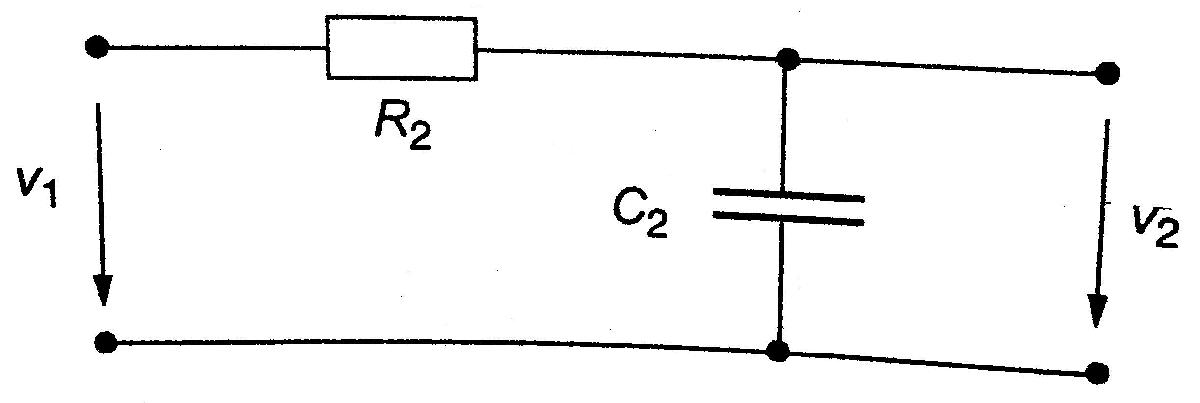

syms A v1 v2 f f_H
A==v2/v1==1/(1+j*f/f_H)

$$ans = \left(A=\frac{v_{2}}{v_{1}}\right)=\frac{1}{1+\frac{f\,\mathrm{i}}{f_{H}}}$$

abs(A)==(1+(f/f_H)^2)^(-1/2)

$$ans = \left|A\right|=\frac{1}{\sqrt{\frac{f^{2}}{{f_{H}}^{2}}+1}}$$

Частота границы пропускания (3 дБ)

syms R2 C2
f_H==1/(2*pi*R2*C2)

$$ans = f_{H}=\frac{1}{2\,C_{2}\,R_{2}\,\pi }$$

Сдвиг фазы v2

theta==-atan(f/f_H)

$$ans = \theta =-\mathrm{atan}\left(\frac{f}{f_{H}}\right)$$

#### Переходная характериситка фильтра низкочастотного пропускания

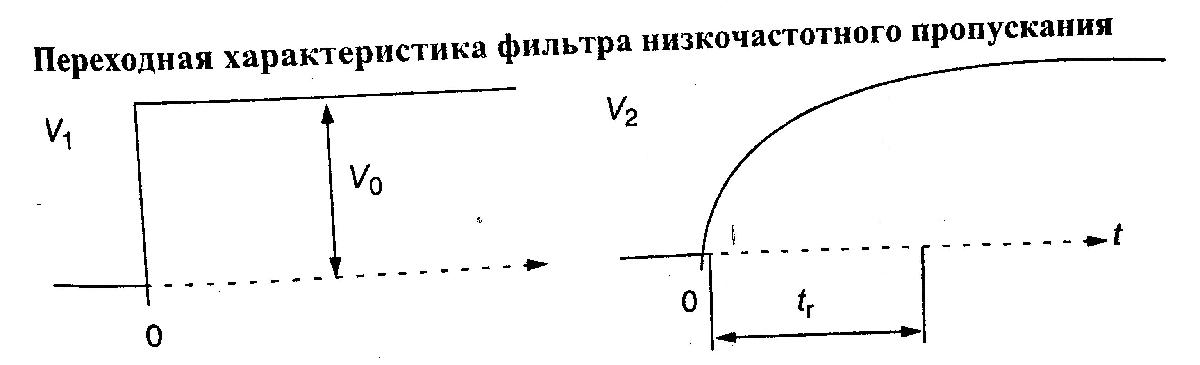

syms V2(t) V0 t
V2(t)==V0*(1-exp(-t/(R2*C2)))

$$ans = V_{2}\left(t\right)=-V_{0}\,\left({\mathrm{e}}^{-\frac{t}{C_{2}\,R_{2}}}-1\right)$$

Время нарастания

syms t_r t10 t90 f_H
t_r==t90-t10==vpa(2.2)*R2*C2==vpa(0.35)/f_H

$$ans = \left(\left(t_{r}=t_{90}-t_{10}\right)=2.2\,C_{2}\,R_{2}\right)=\frac{0.35}{f_{H}}$$

#### Каскадный транзисторный усилитель из n независимых каскадов

syms f_H1 f_H2 f_Hn f_Hs f_L1 f_L2 f_Ln f_Ls
2==(1+(f_Hs/f_H1)^2)*(1+(f_Hs/f_H2)^2)* ... % ...
    (1+(f_Hs/f_Hn)^2)

$$ans = 2=\left(\frac{{f_{\mathrm{Hs}}}^{2}}{{f_{\mathrm{H1}}}^{2}}+1\right)\,\left(\frac{{f_{\mathrm{Hs}}}^{2}}{{f_{\mathrm{H2}}}^{2}}+1\right)\,\left(\frac{{f_{\mathrm{Hs}}}^{2}}{{f_{\mathrm{Hn}}}^{2}}+1\right)$$

2==(1+(f_L1/f_Ls)^2)*(1+(f_L2/f_Ls)^2)* ... % ...
    (1+(f_Ln/f_Ls)^2)

$$ans = 2=\left(\frac{{f_{\mathrm{L1}}}^{2}}{{f_{\mathrm{Ls}}}^{2}}+1\right)\,\left(\frac{{f_{\mathrm{L2}}}^{2}}{{f_{\mathrm{Ls}}}^{2}}+1\right)\,\left(\frac{{f_{\mathrm{Ln}}}^{2}}{{f_{\mathrm{Ls}}}^{2}}+1\right)$$

% f_Ls и f_Hs - низкая и высокая частоты границы пропускания (3 дБ)
% каскадного усилителя

С погрешностью <10% время нарастания

syms t_rs t_r1 r_r2 t_rn
t_rs==vpa(1.1)*sqrt(t_r1^2+r_r2^2+ ... % ...
    t_rn^2)

$$ans = t_{\mathrm{rs}}=1.1\,\sqrt{{r_{\mathrm{r2}}}^{2}+{t_{\mathrm{r1}}}^{2}+{t_{\mathrm{rn}}}^{2}}$$

#### Фильтр Баттеруорта

Каскад j

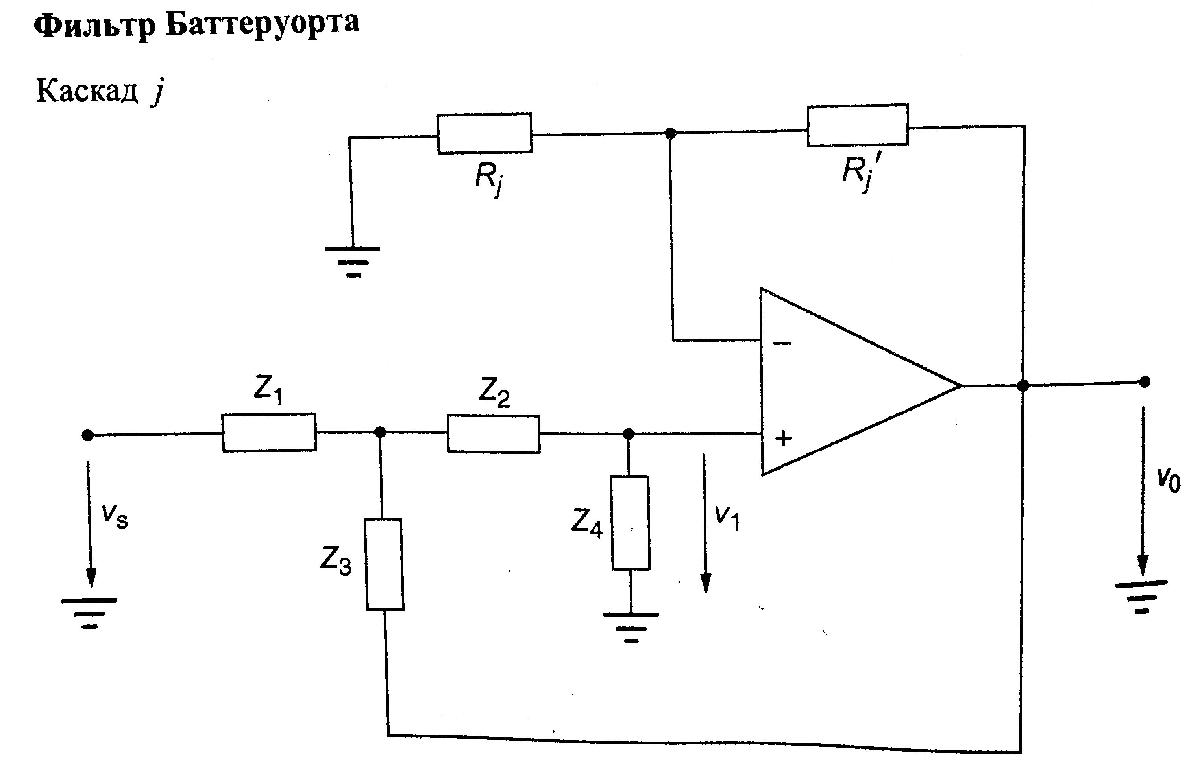

Вариант низкочастотного пропускания

syms Z1 Z2 Z3 Z4 R omega C
Z1==Z2==R, Z3==Z4==1/(j*omega*C)

$$ans = \left(Z_{1}=Z_{2}\right)=R$$

$$ans = \left(Z_{3}=Z_{4}\right)=-\frac{\mathrm{i}}{C\,\omega }$$

Вариант верхних частот

Z1==Z2==1/(j*omega*C), Z3==Z4==R

$$ans = \left(Z_{1}=Z_{2}\right)=-\frac{\mathrm{i}}{C\,\omega }$$

$$ans = \left(Z_{3}=Z_{4}\right)=R$$

Результирующая граница пропускания (3 дБ)

syms f0 omega0 
f0==omega0/(2*pi)==1/(2*pi*R*C)

$$ans = \left(f_{0}=\frac{\omega_{0}}{2\,\pi }\right)=\frac{1}{2\,C\,R\,\pi }$$

Нормированные полиномы Баттеруорта

syms s n
B_n(s)=[s+1; s^2+vpa(1.414)*s+1; (s+1)*(s^2+s+1); (s^2+vpa(0.765)*s+1)*(s^2+vpa(1.848)*s+1)]

$$B\_n(s) = \left(\begin{array}{c} s+1\\ s^{2}+1.414\,s+1\\ \left(s+1\right)\,\left(s^{2}+s+1\right)\\ \left(s^{2}+0.765\,s+1\right)\,\left(s^{2}+1.848\,s+1\right) \end{array}\right)$$

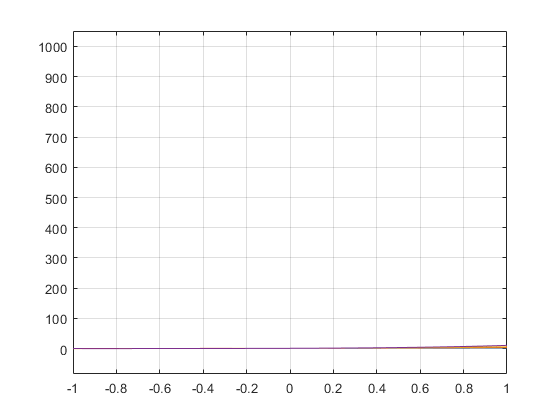

fplot(B_n(s))
xlim([-1 1])
grid

% 2*m
syms s k(j) m
B_n(s)=symprod(s^2+2*k(j)*s+1,j,1,m)

$$B\_n(s) = \prod_{j=1}^{m}\left(s^{2}+2\,k\left(j\right)\,s+1\right)$$

% 2*m+1
B_n(s)=(s+1)*symprod(s^2+2*k(j)*s+1,j,1,m)

$$B\_n(s) = \left(s+1\right)\,\left(\prod_{j=1}^{m}\left(s^{2}+2\,k\left(j\right)\,s+1\right)\right)$$

Коэффициент затухания

syms k(j) theta(j)
k(j)==cos(theta(j))

$$ans = k\left(j\right)=\cos\left(\theta \left(j\right)\right)$$

theta(j)==j*pi/n  % j=1,2,...(n-1)/2 для нечетных n

$$ans = \theta \left(j\right)=\frac{\pi \,j}{n}$$

theta(j)==j*pi/n+pi/(2*n)  % j=1,2,...(n-1)/2 для четных n

$$ans = \theta \left(j\right)=\frac{\pi }{2\,n}+\frac{\pi \,j}{n}$$

Регулировка усиления для каждого каскада

syms A(j) k(j) R1(j) R(j) v0 v1
A(j)==3-2*k(j)

$$ans = A\left(j\right)=3-2\,k\left(j\right)$$

A(j)==v0/v1==1+R1(j)/R(j)

$$ans = \left(A\left(j\right)=\frac{v_{0}}{v_{1}}\right)=\frac{R_{1}\left(j\right)}{R\left(j\right)}+1$$

Полный коэффициент усиления фильтра низкочастотного пропускания n-го порядка

syms A_t v0 v_s A(j) B_n(s) omega0
A_t==v0/v_s==symprod(A(j),j,1,m)/B_n(s/omega0)

$$ans = \left(A_{t}=\frac{v_{0}}{v_{s}}\right)=\frac{\prod_{j=1}^{m}A\left(j\right)}{B_{n}\left(\frac{s}{\omega_{0}}\right)}$$

% s = комплексная угловая частота

Полный коэффициент усиления фильтра верхних частот n-го порядка

A_t==v0/v_s==symprod(A(j),j,1,m)/B_n(omega0/s)

$$ans = \left(A_{t}=\frac{v_{0}}{v_{s}}\right)=\frac{\prod_{j=1}^{m}A\left(j\right)}{B_{n}\left(\frac{\omega_{0}}{s}\right)}$$